clear
clc

[x1,y1] = Heun_sistema('funcion_sistema',0,3,32,[1,1])

x1 =          0
    0.0938
    0.1875
    0.2812
    0.3750
    0.4688
    0.5625
    0.6562
    0.7500
    0.8438


y1 = 	1.0e+05 *

    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0001    0.0000
    0.0001    0.0001
    0.0001    0.0001
    0.0002    0.0002
    0.0002    0.0002


[x2,y2] = Heun_sistema('funcion_sistema',0,3,64,[1,1])

x2 =          0
    0.0469
    0.0938
    0.1406
    0.1875
    0.2344
    0.2812
    0.3281
    0.3750
    0.4219


y2 = 	1.0e+05 *

    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000


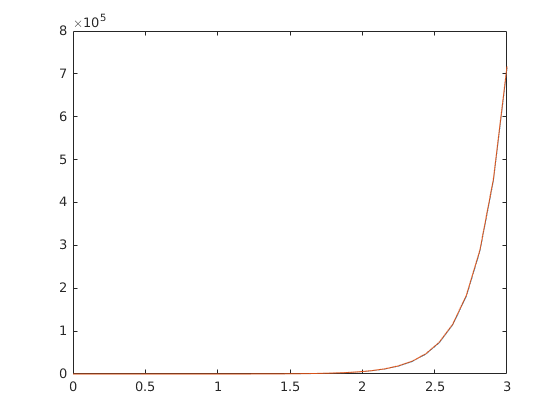

%%% graficar solucion
plot(x1,y1)

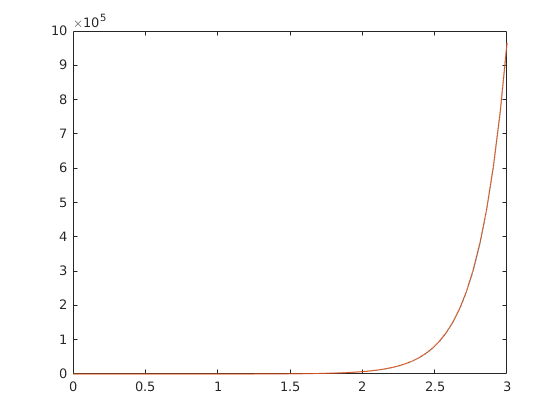

plot(x2,y2)

%%% calculo de error con N=8
solex1 = exp(1/4-(1/2-x1).^2);
error8 = abs(y1(2)-solex1);
%plot(error8) 
%%% Valor maximo del error
error8 = max(error8)

error8 = 1.4234

%%% calculo de error con N=16
solex2 = exp(1/4-(1/2-x2).^2);
error16 = abs(y2(2)-solex2);
%plot(error8) 
%%% Valor maximo del error
error16 = max(error16)

error16 = 1.1980

%%% orden del metodo 2^1 = 2
error8/error16

ans = 1.1881